%Time and frequency range
t = 0:1/20000:1;
f = 0:1:20000;

%Creation of notes in musical scale
Fundamental = sin(2*pi*880*t);
Note_2 = sin(2*pi*880*(6/5)*t);
Note_3 = sin(2*pi*880*(7/5)*t);
Note_4 = sin(2*pi*880*(8/5)*t);
Note_5 = sin(2*pi*880*(9/5)*t);
Harmonic = sin(2*pi*880*2*t);

%Fourier Transform of the Notes to see in freq spectrum
Fund_FFT = abs(fft(Fundamental));
FFT2 = abs(fft(Note_2));
FFT3 = abs(fft(Note_3));
FFT4 = abs(fft(Note_4));
FFT5 = abs(fft(Note_5));
Harm_FFT = abs(fft(Harmonic));

%plot
plot(f,Fund_FFT)
title('My Musical Scale')
xlabel('Frequency(Hz)')
ylabel('Amplitude')
xlim([0 6000])
hold

Current plot held


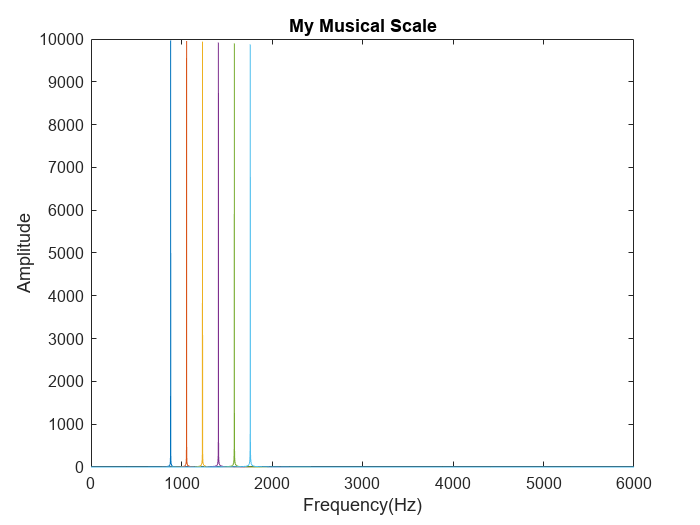

plot(f,FFT2)
plot(f,FFT3)
plot(f,FFT4)
plot(f,FFT5)
plot(f,Harm_FFT)




%Play the sounds
sound(Fundamental,20000)
pause(1)
sound(Note_2,20000)
pause(1)
sound(Note_3,20000)
pause(1)
sound(Note_4,20000)
pause(1)
sound(Note_5,20000)
pause(1)
sound(Harmonic,20000)